# 非局部均值 NLM 图像滤波

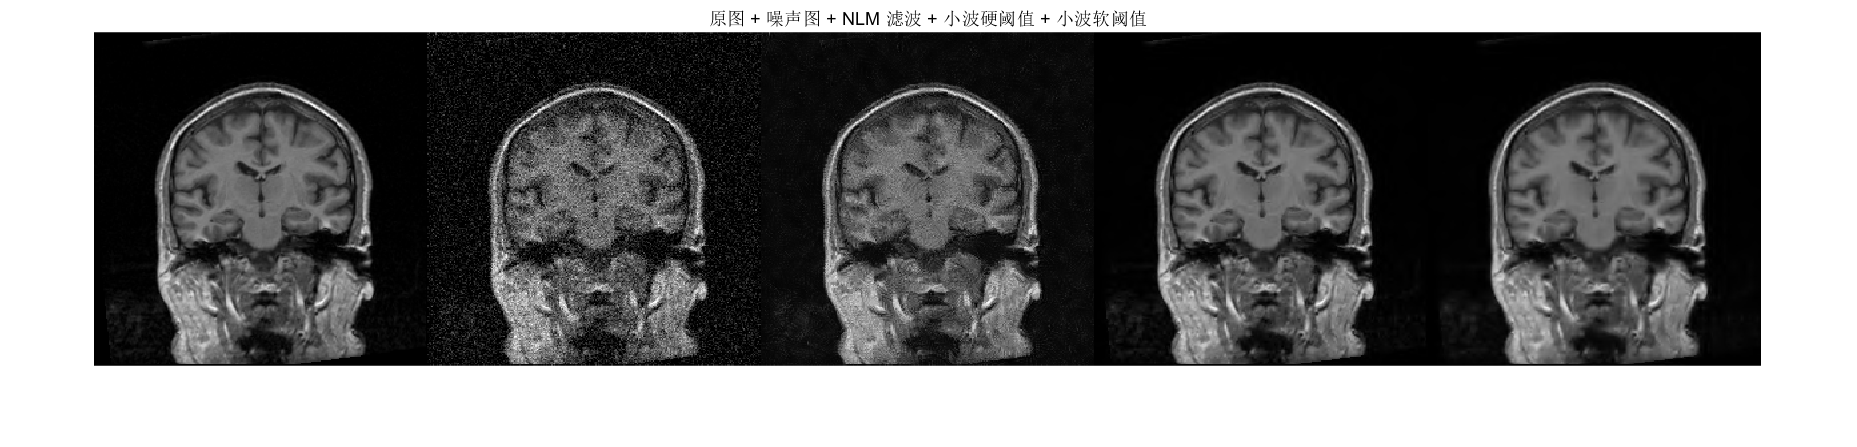

clear;clc;
im = imread('brain.bmp');
if size(im, 3) > 1
    im = rgb2gray(im);
end
rng('default')
im0 = imnoise(im, 'gaussian', 0, 1e-2); % 原图像 + 白噪声
im1 = Nlm2D(im0, 5, 4, 0.15);
% matlab 小波
wname = 'db3'; % 小波类型    
n = 3;         % 分解层数    
sorh1 = 'h';   % 硬阈值    
sorh2 = 's';   % 软阈值    
% 对图像进行小波分解    
[c, l] = wavedec2(im, n, wname);  
% 求取阈值  
N = numel(im);  
[chd1, cvd1, cdd1] = detcoef2('all',c,l,1);   
cvd1 = cvd1(:)';  
sigma = median(abs(cvd1)) / 0.6745; % 提取细节系数求中值并除以0.6745  
thr = sigma*sqrt(2*log(N));   
% 对小波系数全局阈值处理    
cxch = c;   % 保留近似系数    
cxcs = c;   % 保留近似系数    
justdet = prod(l(1, :)) + 1:length(c);  % 截取细节系数（不处理近似系数）    
% 阈值处理细节系数    
cxch(justdet) = wthresh(cxch(justdet), sorh1, thr);  % 硬阈值去噪    
cxcs(justdet) = wthresh(cxcs(justdet), sorh2, thr);  % 软阈值去噪    
% 小波重建    
xch = waverec2(cxch, l, wname);    
xcs = waverec2(cxcs, l, wname);
xch = uint8(xch);
xcs = uint8(xcs);
montage([im, im0, im1, xch, xcs]);
title('原图 + 噪声图 + NLM 滤波 + 小波硬阈值 + 小波软阈值')

function DeNimg = Nlm2D(Nimg, window_width, patch_width, Sigma)
maxi = double(max(max(Nimg)));
if ~isa(Nimg, 'double')
    Nimg = double(Nimg)/maxi;
end
% 图像维数
[m_row, n_col] = size(Nimg);
de_input = zeros(m_row, n_col); % 初始化去噪图像矩阵
de_weigth = de_input; % 初始化权值矩阵
cum_weigth = de_input; % 初始化叠加权值 accumlated weights
% 避免边界效应
PW = padarray(Nimg, [window_width, window_width], 'symmetric', 'both');
PP = padarray(Nimg, [patch_width, patch_width], 'symmetric', 'both');
% 主循环
for dx = -patch_width : patch_width
    for dy = -patch_width : patch_width
        if dx ~= 0 || dy ~= 0
            Sd = integral_img(PW, dx, dy);  % 插值图像
            % 获取对应像素点的平方差矩阵
            SDist = Sd(window_width + 1 : end - window_width, window_width + 1 : end - window_width) + ...
                          Sd(1 : end - 2*window_width, 1 : end - 2*window_width) - ...
                          Sd(1 : end - 2*window_width, window_width + 1 : end - window_width) - ...
                          Sd(window_width + 1 : end - window_width, 1 : end - 2*window_width);       
            % 计算每一个像素点的权值
            w = exp(-SDist/(2*Sigma^2));
            % 得到相应的噪声点
            v = PP((patch_width + 1 + dx) : ( patch_width + dx + m_row), (patch_width + 1 + dy) : (patch_width + dy + n_col));
            % 更新去噪图像矩阵
            de_input = de_input + w .* v;
            % 更新权值去噪图像矩阵
            de_weigth = max(de_weigth, w);
            % 更新叠加权值 accumlated weights
            cum_weigth = cum_weigth + w;
        end
    end
end
% 重构图像        
de_input = de_input + de_weigth .* Nimg;
de_input = de_input ./ (cum_weigth +  de_weigth);
DeNimg = round(de_input*maxi); % 重构去噪图像
end
function Sd = integral_img(v, dx, dy)
% 根据平方差，插值图像
% 变换计算：tx = vx + dx; ty = vy + dy
t = img_Shift(v, dx, dy);
% 平方差图像
diff = (v - t) .^ 2;
% 沿行插值
Sd = cumsum(diff, 1);  % 行叠加
% 沿列插值
Sd = cumsum(Sd, 2);    % 列叠加
end

function t = img_Shift(v, dx, dy)
% 在xy坐标系下，进行图像变换操作
t = zeros(size(v));
type = (dx > 0) * 2 + (dy > 0);
switch type
    case 0 % dx<0,dy<0: 向右下方移动
        t(-dx+1:end,-dy+1:end) = v(1:end+dx,1:end+dy);
    case 1 % dx<0,dy>0: 向左下方移动
        t(-dx+1:end,1:end-dy) = v(1:end+dx,dy+1:end);
    case 2 % dx>0,dy<0: 向右上方移动
        t(1:end-dx,-dy+1:end) = v(dx+1:end,1:end+dy);
    case 3 % dx>0,dy>0: 向左上方移动
        t(1:end-dx,1:end-dy) = v(dx+1:end,dy+1:end);
end
end